# MR Signal Equations

Pulse sequences create an MR signal that depends on the parameters used for that sequence and the tissue properties.  For several pulse sequences, we have equations that describe the expected signal given the parameters.  This tutorial describes and plots some these signals.

This tutorial goes through the sequences and the equations for major pulse sequences.

### Tissue parameters

Here is a table of the T1, T2, and T2* parameters of substrates that we find in the brain.  The table is for a 3T field (the values depend on field strength).  This table could be improved with referencing and a little more searching through the literature.


$$
\matrix{
\textbf{Tissue}    	&  \mathbf{T_1}	& \mathbf{T_2}	& \mathbf{{T_2}^*}   \cr
\hline
\text{White}		& 0.86 			& 0.080	        & 0.067	\cr
\text{Gray}		& 1.20 	  	        & 0.110	        & 0.028	\cr
\text{CSF}		& 4.27     			& 1.58 		& ?	\cr
\text{Arterial blood}	& 1.7			& ?		        & 0.049 		\cr
\text{Venous blood}	        & 1.7 			& ?		 &  0.015		\cr
}
$$


There are a number of  sources that provide these parameters, often in conflict. As I gain more confidence, I may update those values.  Here are the sources so far.

            **Sources**: 

- Jezzard and Clare Chapter 3 in the Oxford fMRI Book.  The numbers differ somewhat between different publications (e.g.,  "[NMR relaxation times in the human brain at 3.0 tesla](https://pubmed.ncbi.nlm.nih.gov/10232510/)")

- Also:  T2* at 1.5T from [http://www.ajnr.org/content/29/5/950](http://www.ajnr.org/content/29/5/950) Table 1.  They have a T2 of 96 ms in GM and 110 in WM 

- T2 at 3T [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5390949/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5390949/) 

- [https://link.springer.com/article/10.1007%2Fs11682-016-9550-5](https://link.springer.com/article/10.1007%2Fs11682-016-9550-5) 

- [https://link.springer.com/article/10.1007/s10334-016-0573-0](https://link.springer.com/article/10.1007/s10334-016-0573-0)

- [https://www.frontiersin.org/articles/10.3389/fnins.2013.00095/full](https://www.frontiersin.org/articles/10.3389/fnins.2013.00095/full) 

- [https://www-sciencedirect-com.stanford.idm.oclc.org/science/article/pii/S1053811917307176?via%3Dihub](https://www-sciencedirect-com.stanford.idm.oclc.org/science/article/pii/S1053811917307176?via%3Dihub) Good table 1, though experimental measurements are at 7T they have a Table 1 that list parameters for 3T (Olivia Wiessman).  The grey matter T1 in that table seems way off (T1 of 2.132 s, citing Rooney et al. 2007.

- [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7897197/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7897197/) 

## Spin Echo

Four parameters define the spin echo signal equations.  Two are pulse sequence choices:  TR (repetition time) and TE (echo time). The other two are material properties (T1 and T2).  

**Question**:  Why doesn't T2* matter for this sequence?

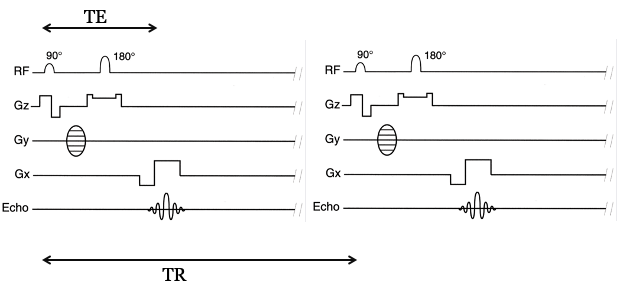

Here is the equation relating SE signal to these parameters:


$$\textrm{signal}\left(\textrm{SE}\right)=\left(1-\exp \left(-\frac{\textrm{TR}}{T_1 }\right)\right)\;\left(e\textrm{xp}\left(-\frac{\textrm{TE}}{T_2 }\right)\right)$$


## Calculating the Spin Echo signal

% Tissue parameters (approximate, and varying across brain)
% These are from the table above
gT1 = 1.2;  gT2 = 0.110; gT2star = 0.11;  
wT1 = 0.8;  wT2 = 0.080; wT2star = 0.08; 
cT1 = 4.27; cT2star = 1.58;

% Here are some sequence properties, pretty standard
%
% We can adjust the timing of the RF and gradients to produce different
% echo times. 
TR = 2;   % sec
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec

% Here are the signal levels as for different echo times
sig = mrSignalEquations('spin echo',...
    'TR',TR,'TE',TE, ...
    'T1',gT1,'T2',gT2);

mrvNewGraphWin;
plot(TE,sig,'Linewidth',2); grid on;
xlabel('TE (ms)'); ylabel('Signal (a.u.)');


Now switch up the tissue for gray matter

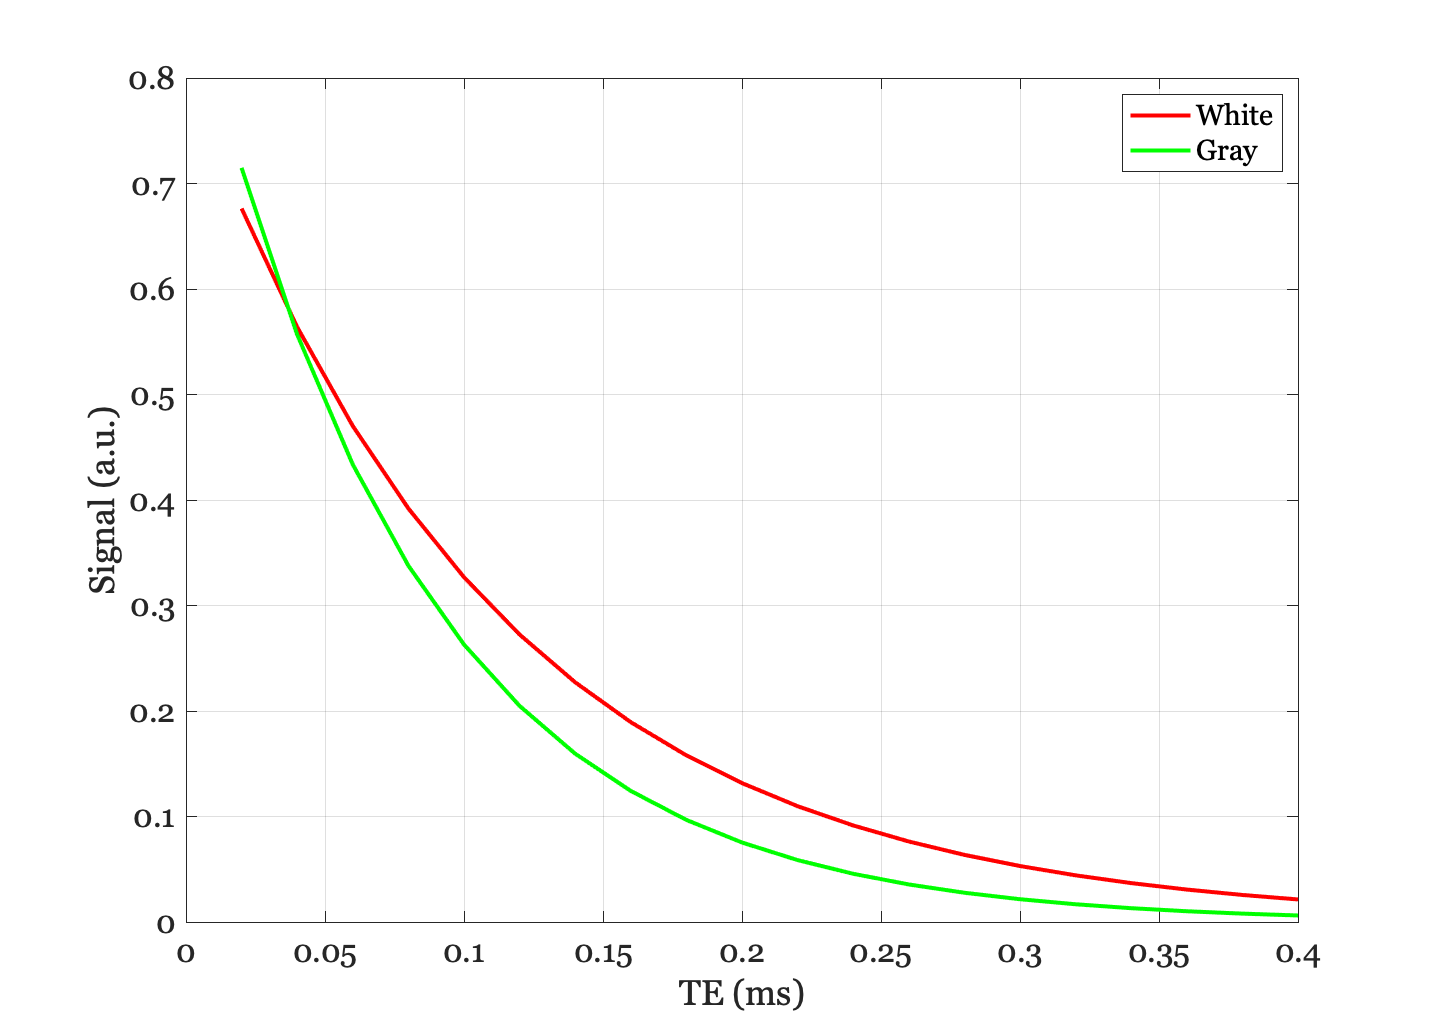

% Tissue properties - for white
T1 = 0.86; % sec
T2 = 0.080;% sec

% Here are the signal levels as for different echo times
sig = mrSignalEquations('spin echo',...
    'TR',TR,'TE',TE, ...
    'T1',wT1,'T2',wT2);

hold on;
plot(TE,sig,'Linewidth',2); grid on;
xlabel('TE (ms)'); ylabel('Signal (a.u.)');

legend({'White','Gray'});

## Gradient Echo

The Gradient Echo (GE) Sequence has this pulse diagram

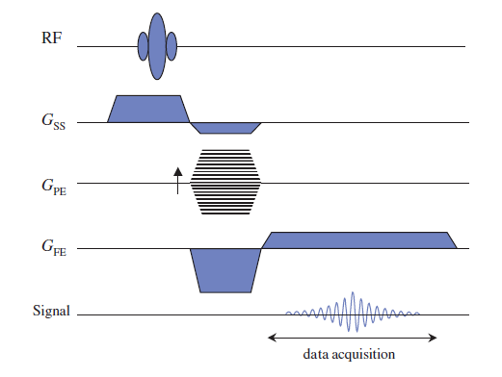

The key parameters for the sequence are the flip angle $$\alpha$$, TR, TE, T1 and T2*.  The formula is

#### 
$$Signal(GE) = M_0 {\frac{sin(\alpha) (1 - exp^{(-TR/{T_1})} )e^{(-TE/{T_2}^*)}}{1 - cos(\alpha)(1 - exp^{-(TR/{T_1})})}$$


## Calculating the GE signal

We can write the parameters and Matlab expression this way

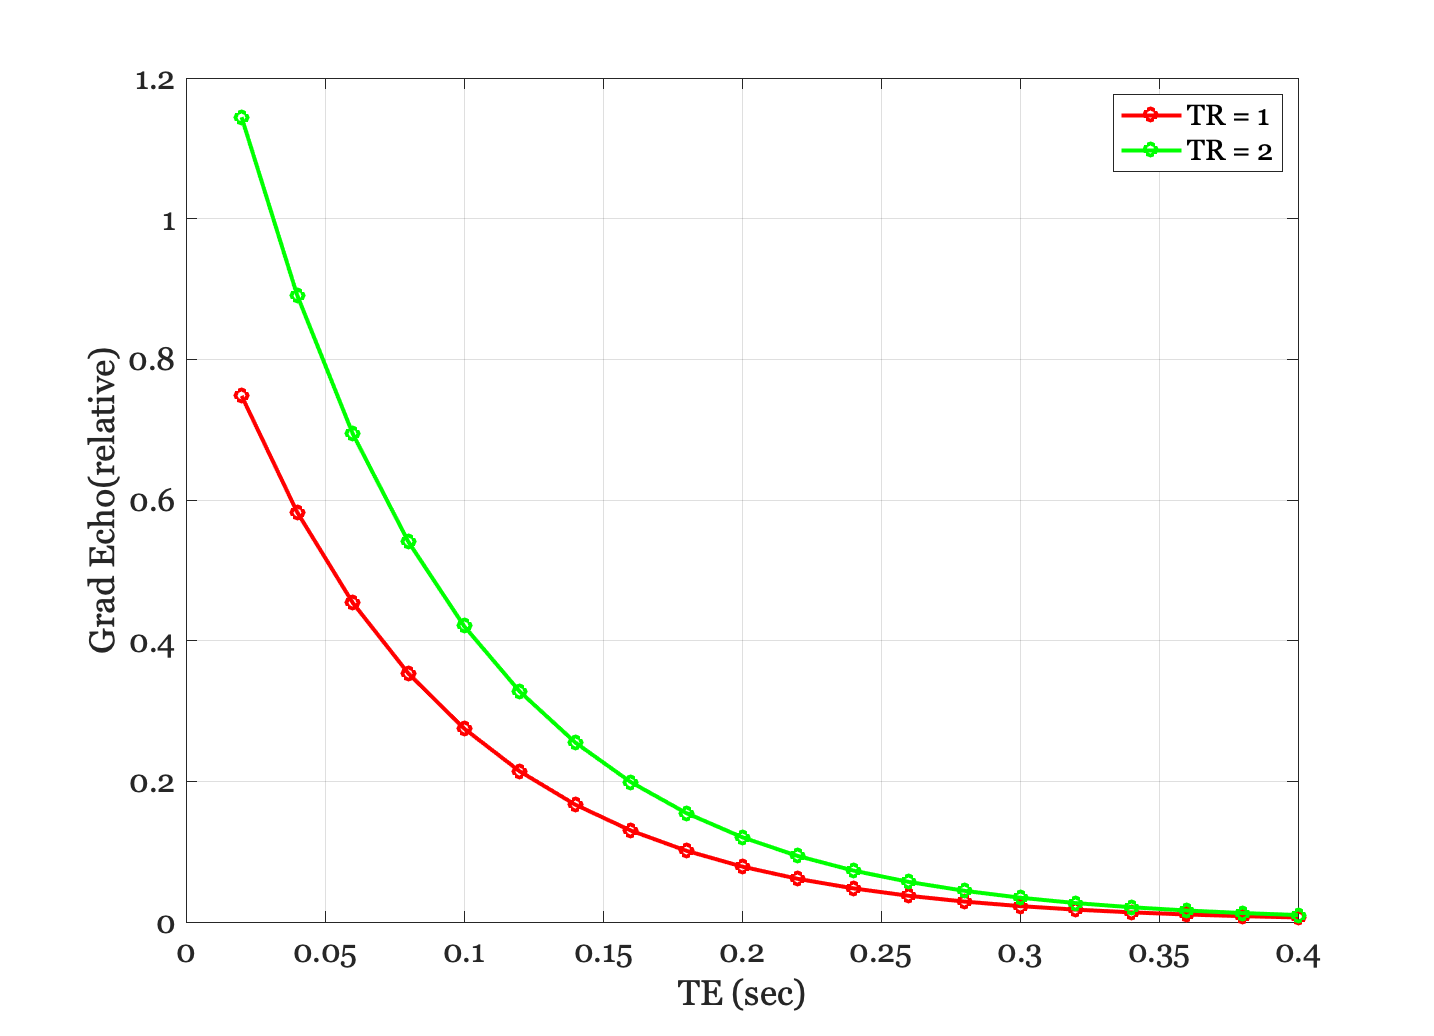

FA = 60;     % deg
T2star = 0.08;  % sec

% Sweep out a set of measurement times for the graident echo
TE = (0.02:0.02:0.40);  % 20 ms to 400 msec

% sind is sine for degree inputs
% The Gradient Echo Signal Equation
TR = 1;
sig = mrSignalEquations('gradient echo',...
    'FA',FA,'TE',TE, 'TR',TR, ...
    'T1',wT1,'T2star',wT2star);

mrvNewGraphWin;
plot(TE,sig,'-o','Linewidth',2);
grid on;
xlabel('TE (sec)'); ylabel('Grad Echo(relative)');

hold on;
TR = 2;
sig = mrSignalEquations('gradient echo',...
    'FA',FA,'TE',TE, 'TR',TR, ...
    'T1',wT1,'T2star',wT2star);
plot(TE,sig,'-o','Linewidth',2);
legend({'TR = 1','TR = 2'})

### Pulse sequence parameters

In a pair of experiments I am analyzing, we used two different Gradient Echo (GE) pulse sequences.  Here are the two sets of parameters.

**Gradient Echo sequence parameters**


$$
\matrix{
\mathbf{Sequence}    	&  \mathbf{TE (s)}	& \mathbf{TR (s)}	& \mathbf{FA (deg)}   \cr
\hline
\mathbf{Resting}		& 0.028 			& 2.00	        & 77	\cr
\mathbf{SMS}		& 0.0116	  	        & 0.25        & 48	\cr
}$$


Set the pulse sequence parameters for resting and sms methods.

% Resting Sequence parameters
rTE = 0.0275; rFA = 77; rTR = 2;

% SMS sequence parameters
sTE = 0.011; sFA = 48; sTR = 0.25;

Calculate signal ratios for the gray matter and the two sequences

meanGRSig = mrSignalEquations('gradient echo',...
    'FA',rFA,'TE',rTE, 'TR',rTR, ...
    'T1',gT1,'T2star',gT2star)

meanGRSig = 0.7529


% SMS
meanGSSig = mrSignalEquations('gradient echo',...
    'FA',sFA,'TE',sTE, 'TR',sTR, ...
    'T1',gT1,'T2star',gT2star)

meanGSSig = 0.1447


fprintf('Gray matter mean signal ratio (GE/SMS) %f\n',meanGRSig/meanGSSig);

Gray matter mean signal ratio (GE/SMS) 5.204428


Now for the white matter

% The Gradient Echo Signal Equation for white matter, resting state
meanWRrSig = mrSignalEquations('gradient echo',...
    'FA',rFA,'TE',rTE, 'TR',rTR, ...
    'T1',wT1,'T2star',wT2star);

% SMS
meanWSSig = mrSignalEquations('gradient echo',...
    'FA',sFA,'TE',sTE, 'TR',sTR, ...
    'T1',wT1,'T2star',wT2star);

% Ratios of the absolute mean signals
fprintf('White matter mean signal ratio (GE/SMS) %f\n',meanWRrSig/meanWSSig);

White matter mean signal ratio (GE/SMS) 3.772262


### Impact of tissue parameter changes

When there is more or less blood in a voxel, we expect the T1 to change.  What happens to the signal if T1 changes? In this case, we are measuring the contrast, not the absolute signal level.  

So let's see how much the signal changes when T1 changes.  It seems a bigger change in SMS than resting

wT1new = wT1 + 0.1;

% Resting state
geT1SensitivityW = mrSignalEquations('gradient echo',...
    'FA',rFA,'TE',rTE, 'TR',rTR, ...
    'T1',wT1new,'T2star',wT2star) / meanWRrSig;

% SMS - contrast
smsT1SensitivityW = mrSignalEquations('gradient echo',...
    'FA',sFA,'TE',sTE, 'TR',sTR, ...
    'T1',wT1new,'T2star',wT2star)  / meanWSSig;

fprintf('White T1 sensitivity (100 ms):  GE %f  ;  SMS %f',geT1SensitivityW,smsT1SensitivityW);

White T1 sensitivity (100 ms):  GE 0.964183  ;  SMS 0.885026

What about if  T2* changes?  A small change in SMS, but a larger change in resting

wT2starnew = wT2star + 0.005;

% Resting
geT2starSensitivityW = mrSignalEquations('gradient echo',...
    'FA',rFA,'TE',rTE, 'TR',rTR, ...
    'T1',wT1,'T2star',wT2starnew)  / meanWRrSig;

% SMS
smsT2starSensitivityW = mrSignalEquations('gradient echo',...
    'FA',sFA,'TE',sTE, 'TR',sTR, ...
    'T1',wT1,'T2star',wT2starnew) / meanWSSig;

fprintf('White T2* sensitivity (5 ms):  GE %f  ;  SMS %f',geT2starSensitivityW,smsT2starSensitivityW);

White T2* sensitivity (5 ms):  GE 1.020426  ;  SMS 1.008121

Now for gray matter and T1

gT1new = gT1 + 0.1;

% Resting state
geT1SensitivityG = mrSignalEquations('gradient echo',...
    'FA',rFA,'TE',rTE, 'TR',rTR, ...
    'T1',gT1new,'T2star',gT2star)   / meanGRSig;

% SMS - contrast
smsT1SensitivityG = mrSignalEquations('gradient echo',...
    'FA',sFA,'TE',sTE, 'TR',sTR, ...
    'T1',gT1new,'T2star',gT2star) / meanGSSig;

fprintf('Gray T1 sensitivity (100 ms):  GE %f  ;  SMS %f',geT1SensitivityG,smsT1SensitivityG);

Gray T1 sensitivity (100 ms):  GE 0.961315  ;  SMS 0.921007

Now for gray matter and T2*

gT2starnew = gT2star + 0.005;

% Resting
geT2starSensitivityG = mrSignalEquations('gradient echo',...
    'FA',rFA,'TE',rTE, 'TR',rTR, ...
    'T1',gT1,'T2star',gT2starnew)   / meanGRSig;

% SMS
smsT2starSensitivityG = mrSignalEquations('gradient echo',...
    'FA',sFA,'TE',sTE, 'TR',sTR, ...
    'T1',gT1,'T2star',gT2starnew)   / meanGSSig;

fprintf('Gray T2* sensitivity (5 ms):  GE %f ; SMS %f',geT2starSensitivityG,smsT2starSensitivityG);

Gray T2* sensitivity (5 ms):  GE 1.010929 ; SMS 1.004357

## [Spoiled Gradient Echo Recalled (link)](https://mriquestions.com/spoiling---what-and-how.html)

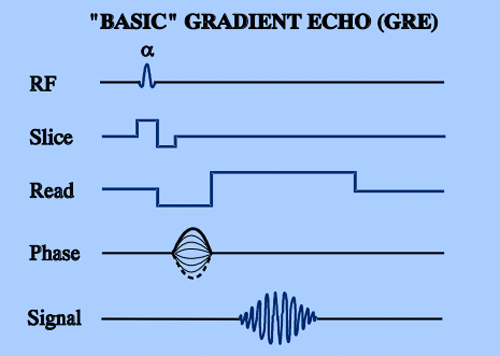 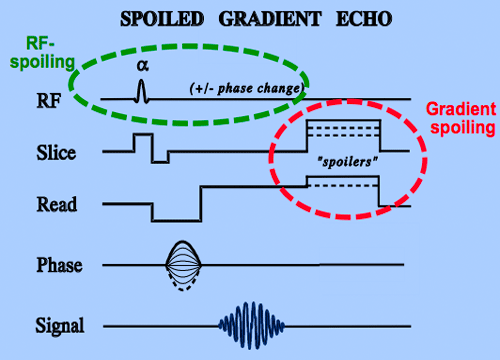

## Inversion Recovery